localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    validationFolder = strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep, "functions", filesep, ...
        "OneTimeScripts", filesep, "validationAgainstOpenDSS_MATLAB");
    cd(validationFolder)
    addpath("rawData\");
    addpath(genpath('dss_matlab\'))
    addpath(genpath('..\..\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end

visible = 'on'; % display voltage snapshot plots (they are still generated and saved either way)

systemName = sysInfo.systemName;
T = simInfo.T;
kVA_B = sysInfo.kVA_B;
kV_B = sysInfo.kV_B;
CVR = [0 0];

DSSObj = DSS_MATLAB.IDSS;

DSSText=DSSObj.Text;
DSSCircuit=DSSObj.ActiveCircuit;
DSSBus = DSSCircuit.ActiveBus;

strSetPath = strcat('Set DataPath = "', char(validationFolder), '"');
DSSText.Command = strSetPath;

MasterFileString = strcat('Compile (.\', systemName, 'master_r.dss)'); 
DSSText.Command = MasterFileString;
text_powerdata_r = 'powerdata.txt';
Power_data = readmatrix(text_powerdata_r);
varNames0 = {"busNum", "P_L", "Q_L", "Q_C", "P_D", "busType"};
varNames = cellfun(@char, varNames0, 'UniformOutput', false);
busData = readtable(text_powerdata_r);
busData.Properties.VariableNames = varNames;

N = length(busData.busNum);
busNums = busData.busNum;
P_L = busData.P_L;
Q_L = busData.Q_L;
Q_C = busData.Q_C;

V_opds_1toT = zeros(N, T);

% disc (discrepancy) will be a struct() which will store the key
% discrepancy values between my MPOPF sim and the validation values by
% OpenDSS
disc = struct();
disc.V_1toT = ones(N, T);
disc.maxV = 1.0;
disc.PLoss_1toT_kW = ones(T, 1);
disc.maxPLoss_kW = 1.0;
disc.PSubs_1toT_kW = ones(T, 1);
disc.maxPSubs_kW = 1.0;

## Load dss generation

loadShape = vald.loadShape;
strLoadShape = strcat('New Loadshape.LoadShape npts = ', num2str(T), ' interval = 1 mult = [', num2str(loadShape'), ']')

strLoadShape = 'New Loadshape.LoadShape npts =1 interval = 1 mult = [0.787]'

DSSText.Command = strLoadShape;

stLoadTitle = '! Specifying Loads as Model 1 and 2 type loads. For no CVR, Model 2 loads will be blank';
DSSTest.Command = stLoadTitle;

for i = 1:N
    if P_L(i) || Q_L(i)
        % Model=1 is constant power load, Model=2 is constant current load
        sta1 = strcat('New load.S', num2str(busNums(i)),'P    Bus=',num2str(busNums(i)),...
            '.1   Phases=1   Model=1   kv=2.4018   kw=',num2str(P_L(i)*(1-(CVR(1)/2))),...
            '  kvar=',num2str(Q_L(i)*(1-(CVR(2)/2))),'   Vminpu=0.95  Vmaxpu=1.05 Daily = LoadShape');
        
       DSSText.Command = sta1;

       if CVR ~= [0 0] %#ok
           sta2 = strcat('New load.S', num2str(busNums(i)),'Z    Bus=',num2str(busNums(i)),...
               '.1   Phases=1  Model=2   kv=2.4018   kw=',num2str(P_L(i)*((CVR(1))/2)),...
               '  kvar=',num2str(Q_L(i)*((CVR(2))/2)),'    Vminpu=0.95  Vmaxpu=1.05 Daily = LoadShape');
              DSSText.Command = sta2;
       end
    end
end

## Line parameter

text_linedata_r = 'linedata.txt';
Line_data = readmatrix(text_linedata_r);

nBranch = size(Line_data,1);
for i = 1:nBranch
    stLn = strcat('New Line.L', num2str(i),'   Phases = 1  Bus1= ', num2str(Line_data(i,1)),'  bus2 = ',...
        num2str(Line_data(i,2)),'  r1=', num2str(Line_data(i,3)),...
        '  x1= ',num2str(Line_data(i,4)));
    DSSText.Command =stLn;
end

## PV Data

simName = vald.simInfo.simName;
% V_copf_1toT = vald.V_copf;
V_1toT = vald.V_1toT;
busesWithDERs = vald.busesWithDERs;
nDER = vald.nDER;
Pmpp_kW = kVA_B*vald.Pmpp;
% PmppFull_kW = kVA_B*vald.PmppFull;
% kVAFull_kVA = kVA_B*vald.SderFull;
pD_1toT_kW = kVA_B*vald.pD_1toT;
qD_1toT_kVAr = kVA_B*vald.qD_1toT;
SDer_kVA = kVA_B*vald.Sder;
% loadShapePV = vald.loadShapePV;

% strLoadShapePV = strcat('New Loadshape.LoadShapePV npts = ', num2str(T), ' interval = 1 mult = [', num2str(loadShapePV'), ']')

% DSSText.Command = strLoadShapePV;
% tempsArray = 25*ones(1, T);
% strTShapePV = strcat('New tShape.TShapePV npts = ', num2str(T), ' interval = 1 temp = [', num2str(tempsArray), ']')
% DSSText.Command = strTShapePV;

% strEffCurvePV = strcat('New XYCurve.EffCurvePV npts = 4 xarray = [.1 .2 .4 1.0] yarray = [1.0 1.0 1.0 1.0]');
% DSSText.Command = strEffCurvePV;

% strPvsTPV = strcat('New XYCurve.PvsTPV npts = 4 xarray = [0 25 75 100] yarray = [1.2 1 .8 .6]');
% DSSText.Command = strPvsTPV;

% for bus1 = busesWithDERs'
for derBusNum = 1:nDER
    bus1 = busesWithDERs(derBusNum);
    % Pmpp_j_kW = PmppFull_kW(bus1);
    Pmpp_j_kW = Pmpp_kW(derBusNum);
    kVA_j_kVA = SDer_kVA(derBusNum);
    % kVA_j_kVA = kVAFull_kVA(bus1);

    % stGa = strcat('New PVSystem.PV', num2str(bus1), ' irrad = 1.0 Phases = 1   Bus1 = ', num2str(bus1), ...
    %     '.1  kV = ', num2str(kV_B), ' kVA = ', num2str(kVA_j_kVA),  ...
    %     ' Pmpp = ', num2str(Pmpp_j_kW), ' Daily = LoadShapePV TDaily = TShapePV EffCurve = EffCurvePV  P-TCurve = PvsTPV', ...
    %     ' %cutin = 0.1 %cutout = 0.1');

    stGa = strcat('New PVSystem.PV', num2str(bus1), ' irrad = 1.0 Phases = 1   Bus1 = ', num2str(bus1), ...
    '.1  kV = ', num2str(kV_B), ' kVA = ', num2str(kVA_j_kVA),  ...
    ' Pmpp = ', num2str(Pmpp_j_kW) );

    DSSText.Command = stGa;      
end

## Storage

busesWithBatts = vald.busesWithBatts;
B0_kWh = kVA_B*vald.B0;
B_1toT = kVA_B*vald.B_1toT;
S_battRated_kVA = kVA_B*vald.S_battRated;
P_battRated_kW = kVA_B*vald.P_battRated;
nBatt = vald.nBatt;
chargeToPowerRatio = simInfo.chargeToPowerRatio;
V_min = simInfo.V_min;
V_max = simInfo.V_max;
etta_C = simInfo.etta_C;
etta_D = simInfo.etta_D;
soc_min = simInfo.soc_min;
soc_max = simInfo.soc_max;

for battBusNum = 1:nBatt
    bus1 = busesWithBatts(battBusNum);
    kVArated = S_battRated_kVA(battBusNum);
    kWrated = P_battRated_kW(battBusNum);
    kWhrated = chargeToPowerRatio*kWrated;
    percentStored = 100*(soc_min + soc_max)/2;
    percentReserve = soc_min*100;
    percentEffCharge = etta_C*100;
    percentEffDischarge = etta_D*100;
    Vminpu = V_min;
    Vmaxpu = V_max;

    strStorage = strcat('New Storage.Battery', num2str(bus1), ' phases = 1 bus1 = ', num2str(bus1), ...
        ' kV = ', num2str(kV_B), ' kVA = ', num2str(kVArated), ' kWrated = ', num2str(kWrated), ...
        ' kWhrated = ', num2str(kWhrated), ...
        ' %stored = ', num2str(percentStored), ' %reserve = ', num2str(percentReserve), ' %EffCharge = ', ...
        num2str(percentEffCharge), ' %EffDischarge = ', num2str(percentEffDischarge), ' %idlingkW = 0', ...
        ' Vminpu = ', num2str(Vminpu), ' Vmaxpu = ', num2str(Vmaxpu), ' DispMode = Follow');

    DSSText.Command = strStorage;

    strMonStorage = strcat('New Monitor.Battery', num2str(bus1), '_states', ' element = Storage.Battery', num2str(bus1), ' mode=3');
    DSSText.Command = strMonStorage;

end


## Storage Controller

Pd_1toT_kW = kVA_B*vald.Pd_1toT;
Pc_1toT_kW = kVA_B*vald.Pc_1toT;
Pdc_1toT_kW = Pd_1toT_kW - Pc_1toT_kW;

for battBusNum = 1:nBatt
    bus1 = busesWithBatts(battBusNum);
    dispatch = Pdc_1toT_kW(battBusNum, 1:T) / P_battRated_kW(battBusNum);

    strLoadShapeSC = strcat('New LoadShape.SCLoadShape', num2str(bus1), ' interval = 1 npts = ', num2str(T), ' mult = [', num2str(dispatch), ']');

    DSSText.Command = strLoadShapeSC;

    strSC = strcat('New StorageController.SC', num2str(bus1), ' Element = Line.L1', ' terminal = 1', ' ElementList = [Battery', num2str(bus1), ']', ' modedis = loadshape', ' daily = SCLoadShape', num2str(bus1), ' eventlog = yes');

    DSSText.Command = strSC;

end

## Capacitors

smallkW = 0.000001;
% smallkW = 0
for i = 1:N
    if Q_C(i)
        stC = strcat('New generator.',num2str(busNums(i)),'C','  Phases=1   Bus1=',num2str(busNums(i)),...
            '   kV = 2.4018 Model=1 kW=',num2str(smallkW),'   kVAr = ',num2str(Q_C(i)));
        % stC = strcat('New Capacitor.C',num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
        %     '   kV = 2.4018 kVAr=',num2str(Q_C(i)));
        DSSText.Command = stC;
    end
end



## Set Simulation Parameters

DSSText.Command = 'Set VoltageBases = [4.16]' ; %  ! ARRAY OF VOLTAGES IN KV
DSSText.Command = 'Set mode = Daily ';
DSSText.Command = 'Set stepsize = 1h'; 

## Set, Solve, Save, Repeat

qB_1toT_kVAr = kVA_B*vald.qB_1toT;

DSSText.Command = strcat('Set number = 1');

for t = 1:T

    DSSText.Command = strcat('Set hour = ', num2str(t-1));

    qB_t_kVAr = qB_1toT_kVAr(:, t);
    for battBusNum = 1:nBatt
        bus1 = busesWithBatts(battBusNum);
        qBj_t_kVAr = qB_t_kVAr(battBusNum);
        strStorageQ = strcat( 'Edit Storage.Battery', num2str(bus1), ' kVAr = ', num2str(qBj_t_kVAr) );
    
        DSSText.Command = strStorageQ;
    end

    qD_t_kVAr = qD_1toT_kVAr(:, t);
    pD_t_kW = pD_1toT_kW(:, t);
    for derBusNum = 1:nDER
        bus1 = busesWithDERs(derBusNum);
        qDj_t_kVAr = qD_t_kVAr(derBusNum);
        pDj_t_kW = pD_t_kW(derBusNum);
        strPVQ = strcat( 'Edit PVSystem.PV', num2str(bus1), ' Pmpp = ', num2str(pDj_t_kW), ' kVAr = ', num2str( qDj_t_kVAr) );

        DSSText.Command = strPVQ;
    end

    DSSText.Command = 'CalcVoltageBases' ; %! PERFORMS ZERO LOAD POWER FLOW TO ESTIMATE VOLTAGE BASES
    
    DSSSolution     = DSSCircuit.Solution;
    
    DSSObj.AllowForms = false;

    DSSSolution.Solve; 

### Saving Loads for `t`

    Loads = DSSCircuit.Loads;
    loadnumber = Loads.First();
    loadkWsum = 0.0;
    loadkvarsum = 0.0;
    
    while loadnumber > 0
        loadkWsum = loadkWsum + Loads.kW() * loadShape(t);
        loadkvarsum = loadkvarsum + Loads.kvar() * loadShape(t);
        loadnumber = Loads.Next();
    end

### Saving capacitor injected kvars

    Capacitors = DSSCircuit.Generators;
    capNum = Capacitors.First();
    qC_Total_t_kVAr = 0.0;
    while capNum > 0
        qC_Total_t_kVAr = qC_Total_t_kVAr + Capacitors.kVAr();
        capNum = Capacitors.Next();
    end

### Saving generated powers of PVs at `t`

    PVSystems = DSSCircuit.PVSystems;

    % Initialize variables to sum the generation values
    derBusNum = PVSystems.First();
    pD_Total_t_kW = 0.0;
    pD_Total_t_kW1 = 0.0;
    qD_Total_t_kVAr = 0.0;
    
    % Iterate through each generator
    while derBusNum > 0
        pD_Total_t_kW = pD_Total_t_kW + PVSystems.kW();
        qD_Total_t_kVAr = qD_Total_t_kVAr + PVSystems.kvar();
        derBusNum = PVSystems.Next();
    end
    
    % Now pD_Total_t_kW and qD_Total_t_kVAr hold the total kW and kVAr PV generation, respectively

### Saving generated powers of Storage at `t`

    Storages = DSSCircuit.Storages;
    StorageNames = Storages.AllNames;
    StorageNamesFull = strcat('Storage.', StorageNames); % a cell array of names
    Pdc_Total_t_kW = 0.0;
    qB_Total_t_kVAr = 0.0;
    
    DSSActiveElement = DSSCircuit.ActiveCktElement;
    for battBusNum = 1:nBatt
        storageName = StorageNamesFull{battBusNum};
        DSSCircuit.SetActiveElement(storageName);
        sBj_t_kVA = DSSActiveElement.Powers;
        Pdcj_t_kW = -sBj_t_kVA(1);
        qBj_t_kVAr = -sBj_t_kVA(2);  
        Pdc_Total_t_kW = Pdc_Total_t_kW + Pdcj_t_kW;
        qB_Total_t_kVAr = qB_Total_t_kVAr + qBj_t_kVAr;
    end

    Pged_Total_t_kW = pD_Total_t_kW + Pdc_Total_t_kW;
    Qged_Total_t_kVAr = qD_Total_t_kVAr + qB_Total_t_kVAr;
    Q_Total_t_kVAr = Qged_Total_t_kVAr + qC_Total_t_kVAr;

###     Save .DSS file

    ext = ".dss";
    filename = char(strcat(systemName, "_", simName, "_T_", string(T), "_t_", string(t), ext))

filename = 'ieee123_MPCOPF_T_1_t_1.dss'

    saveCommand = ['Save Circuit "', filename, '"'];
    DSSText.Command = saveCommand;
    disp(strcat("DSS file exported to ", filename));

DSS file exported to ieee123_MPCOPF_T_1_t_1.dss


###     Extract Voltages

    V_PU = DSSCircuit.AllBusVmagPU;
    MytotalCircuitLosses= (DSSCircuit.Losses)/1000;
    
    DSSCircuit.SetActiveElement('Line.L1');
    MyPowerArray = DSSCircuit.ActiveCktElement.Powers;
    PSubs_opds_t_kW = sum(MyPowerArray(1));
    
    disc_PSubs_t_kW = abs(PSubs_opds_t_kW - kVA_B*vald.res.PSubs_1toT(t));
    disc.PSubs_1toT_kW(t) = disc_PSubs_t_kW;
    
    QSubs_opds_t_kVAr = sum(MyPowerArray(2));
    SLoss_t_opds_kVA = MytotalCircuitLosses;
    PLoss_t_opds_kW = SLoss_t_opds_kVA(1);
    QLoss_t_opds_kVAr = SLoss_t_opds_kVA(2);

    disc_PLoss_t_kW = abs( PLoss_t_opds_kW - kVA_B*vald.res.PLoss_1toT(t));
    disc.PLoss_1toT_kW(t) = disc_PLoss_t_kW;

    BUS_phase = DSSCircuit.AllNodeNames;
    for i = 1:length(BUS_phase)
        X = BUS_phase{i};
        X_len = length(X);
        % col = str2double(X(end));
        row = str2double(X(1:(X_len-2)));
        V_opds_1toT( row, t) = V_PU(i);
    end
    
    % disc_V_t = abs(V_opds_1toT(1:N, t) - V_copf_1toT(1:N, t));
    disc_V_t = abs(V_opds_1toT(1:N, t) - V_1toT(1:N, t));
    disc.V_1toT(1:N, t) = disc_V_t;


    disp('-----------------------------')

-----------------------------


    disp(['Hour: ', num2str(t)])

Hour: 1


    disp(['Line Loss: ', num2str(PLoss_t_opds_kW),' kW'])

Line Loss: 15.7937 kW


    disp(['Substation Power: ', num2str(PSubs_opds_t_kW),' kW + ', num2str(QSubs_opds_t_kVAr),' kVAr'])

Substation Power: 866.3602 kW + 163.4 kVAr


    disp(['Total Load: ', num2str(loadkWsum), ' kW + ', num2str(loadkvarsum), ' kVAr'])

Total Load: 915.436 kW + 503.6894 kVAr


    disp(['Total Generation: ', num2str(Pged_Total_t_kW), ' kW + ', num2str(Q_Total_t_kVAr), ' kVAr' ])

Total Generation: 64.8373 kW + 370.9351 kVAr


    disp(['Total PV Generation: ', num2str(pD_Total_t_kW), ' kW + ', num2str(qD_Total_t_kVAr), ' kVAr'])

Total PV Generation: 31.4937 kW + 10.4684 kVAr


    disp(['Total Battery Generation: ', num2str(Pdc_Total_t_kW), ' kW + ', num2str(qB_Total_t_kVAr), ' kVAr'])

Total Battery Generation: 33.3436 kW + 10.4667 kVAr


    disp(['Total Static Capacitor Reactive Power Generation: ', num2str(qC_Total_t_kVAr), ' kVAr'])

Total Static Capacitor Reactive Power Generation: 350 kVAr


###     Validate Simulation Against OpenDSS via System-wide Voltage Snapshot

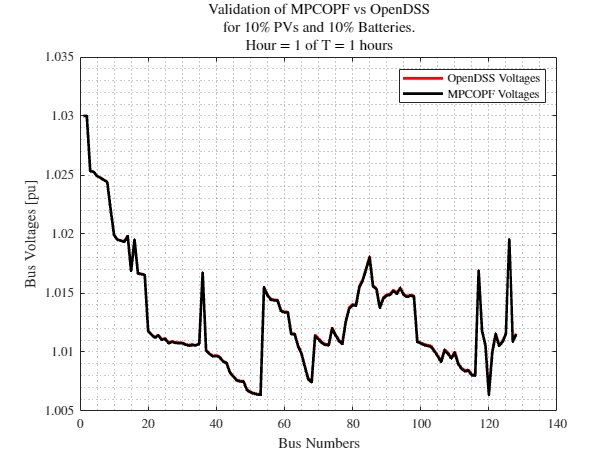

    DER_percent = vald.simInfo.DER_percent;
    Batt_percent = vald.simInfo.Batt_percent;
    if strcmp(visible, 'on')
        figure
    else
        figure('Visible', 'off')
    end

    linewidth = 2.0;
    plot(V_opds_1toT(:, t), 'LineWidth', linewidth, 'Color', 'r');
    hold on;
    % plot(V_copf_1toT(:, t), 'LineWidth', linewidth, 'Color', 'k')
    plot(V_1toT(:, t), 'LineWidth', linewidth, 'Color', 'k')
    legend({"OpenDSS Voltages", strcat(simName, " Voltages")});
    title([strcat("Validation of ", simName, " vs OpenDSS"), strcat("for ", string(DER_percent), "\% PVs and ", string(Batt_percent), "\% Batteries."), ...
        strcat("Hour = ", string(t), " of T = ", string(T), " hours")]);
    ylabel("Bus Voltages [pu]")
    xlabel("Bus Numbers");
    grid minor;
    hold off;
    ext = ".png";
    figureFolder = "figures";
    isfolder(figureFolder) || mkdir(figureFolder); %#ok
    filename = strcat("MPOPF_vs_OpenDSS_T_", string(T), "_t_", string(t), "_pv_", string(DER_percent), "_batt_", string(Batt_percent), ext);
    saveFigure = true;
    addr = strcat(figureFolder, filesep, filename);
    myexportgraphics(saveFigure, gcf, addr, 'Resolution', 300);


end

## Export Monitors

for battBusNum = 1:nBatt
    bus1 = busesWithBatts(battBusNum);
    strExportMonitor =  strcat('Export Monitors Battery', num2str(bus1), '_states');
    DSSText.Command = strExportMonitor;
    strLoads = strcat('Export Loads');
    DSSText.Command = strLoads;
    strSummary = strcat('Export Summary');
    DSSText.Command = strSummary;
    % strGenerators = strcat('Export Powers');
    % DSSText.Command = strGenerators;
end

resultsFolder = strcat(".", filesep, "results", filesep, battstring);

batteryMonitorFolder = strcat(resultsFolder, filesep, "batteryMonitors");

createFolderIfNotExisting(batteryMonitorFolder);

circuitName = DSSCircuit.Name;

moveBatteryMonitorFiles(circuitName, busesWithBatts, nBatt, batteryMonitorFolder);


### Store Maximum Discrepancies

disc.maxV = max(max(disc.V_1toT));
disc.maxPLoss_kW = max(disc.PLoss_1toT_kW);
disc_maxPSubs_kW = max(disc.PSubs_1toT_kW);

disp('-----------------------------')

-----------------------------


disp(['Horizon Period (hourly time-steps): ', num2str(T), ' h']);

Horizon Period (hourly time-steps): 1 h


disp(['GED Penetration: ', num2str(DER_percent), '% PVs + ', num2str(Batt_percent), '% Batteries']);

GED Penetration: 10% PVs + 10% Batteries


disp(['Maximum All Time Voltage Discrepancy: ', num2str(disc.maxV), ' pu'])

Maximum All Time Voltage Discrepancy: 8.7632e-05 pu


disp(['Maximum All Time Line Loss Discrepancy: ', num2str(disc.maxPLoss_kW), ' kW'])

Maximum All Time Line Loss Discrepancy: 0.011456 kW


disp(['Maximum All Time Substation Borrowed Real Power Discrepancy: ', num2str(disc_maxPSubs_kW), ' kW'])

Maximum All Time Substation Borrowed Real Power Discrepancy: 0.042763 kW


disp('-----------------------------')

-----------------------------
